# Tutorial 5: Running Inverse Dynamics in CASPR

Inverse dynamics for cable-driven robots (CDRs) refer to the determination of the set of cable forces for a given desired motion and wrench to be executed.

This tutorial shows how to run inverse dynamics through two approaches:

- InverseDynamicsSimulator

- Writing your own time loop

## Setup (required for both approaches)

### Load the robot and trajectory 

Load a robot as shown in `tutorial_load_robot.mlx `and` tutorial_load_trajectory.mlx`

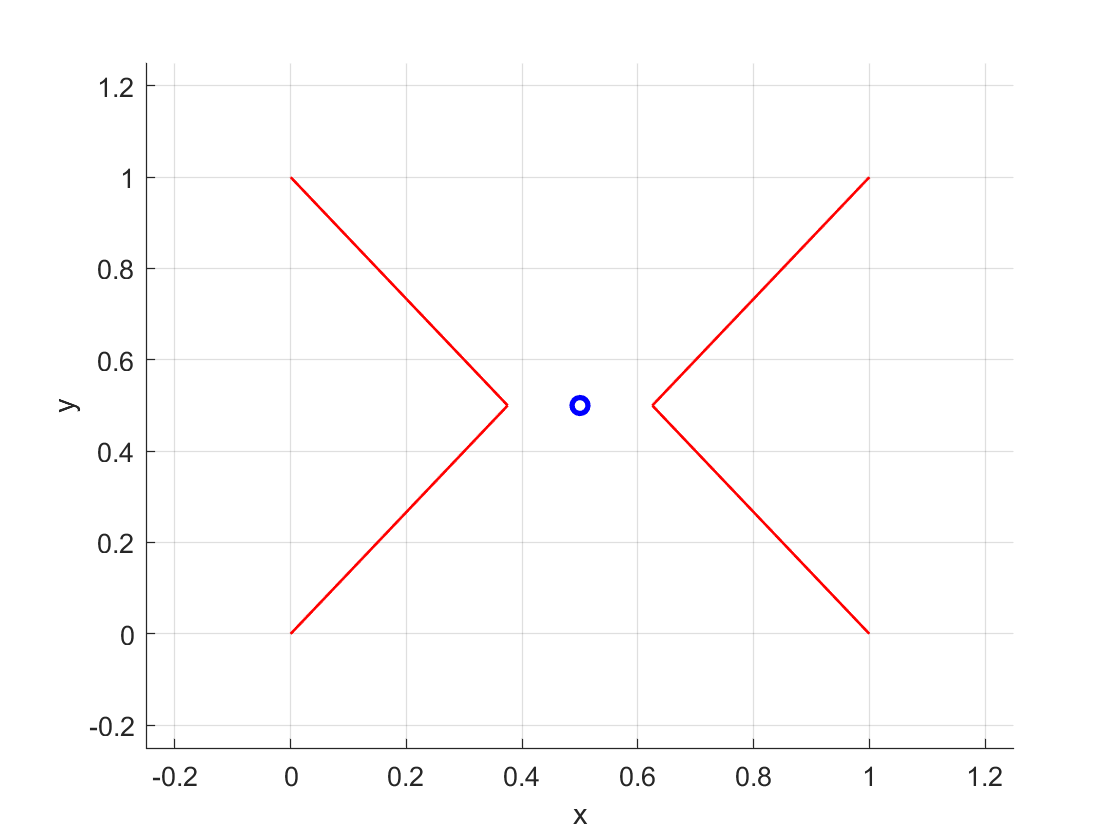

model_config = ModelConfig('Example planar XY');
cdpr_model = model_config.getModel('basic');
trajectory = model_config.getJointTrajectory('example_quintic');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot

### Setup inverse dynamics solver

Since there are many different methods to solve for the inverse dynamics, different solvers can be setup to be used in CASPR. For the sake of example, the most common quadratic programming (QP) method with an objective function of minimising the sum of the squared of cable forces will be shown in this example:

min_forces_objective = IDObjectiveMinQuadCableForce(ones(cdpr_model.numActuatorsActive,1));
id_solver = IDSolverQuadProg(cdpr_model, min_forces_objective, ID_QP_SolverType.MATLAB);

## 1) Using the InverseDynamicsSimulator

The `InverseDynamicsSimulator` provides the simplest way to run a "standard" inverse dynamics simulation for a defined trajectory. 

First, create the simulator object using the robot model and the specified solver:

id_sim = InverseDynamicsSimulator(cdpr_model, id_solver);

Next, run the simulator on a particular trajectory

id_sim.run(trajectory);

[INFO] Time : 0.000000
[INFO] Time : 0.050000
[INFO] Time : 0.100000
[INFO] Time : 0.150000
[INFO] Time : 0.200000
[INFO] Time : 0.250000
[INFO] Time : 0.300000
[INFO] Time : 0.350000
[INFO] Time : 0.400000
[INFO] Time : 0.450000
[INFO] Time : 0.500000
[INFO] Time : 0.550000
[INFO] Time : 0.600000
[INFO] Time : 0.650000
[INFO] Time : 0.700000
[INFO] Time : 0.750000
[INFO] Time : 0.800000
[INFO] Time : 0.850000
[INFO] Time : 0.900000
[INFO] Time : 0.950000
[INFO] Time : 1.000000
[INFO] Time : 1.050000
[INFO] Time : 1.100000
[INFO] Time : 1.150000
[INFO] Time : 1.200000
[INFO] Time : 1.250000
[INFO] Time : 1.300000
[INFO] Time : 1.350000
[INFO] Time : 1.400000
[INFO] Time : 1.450000
[INFO] Time : 1.500000
[INFO] Time : 1.550000
[INFO] Time : 1.600000
[INFO] Time : 1.650000
[INFO] Time : 1.700000
[INFO] Time : 1.750000
[INFO] Time : 1.800000
[INFO] Time : 1.850000
[INFO] Time : 1.900000
[INFO] Time : 1.950000
[INFO] Time : 2.000000
[INFO] Time : 2.050000
[INFO] Time : 2.100000
[INFO] Time

Finally, the simulator can plot the results, such as the cable lengths:

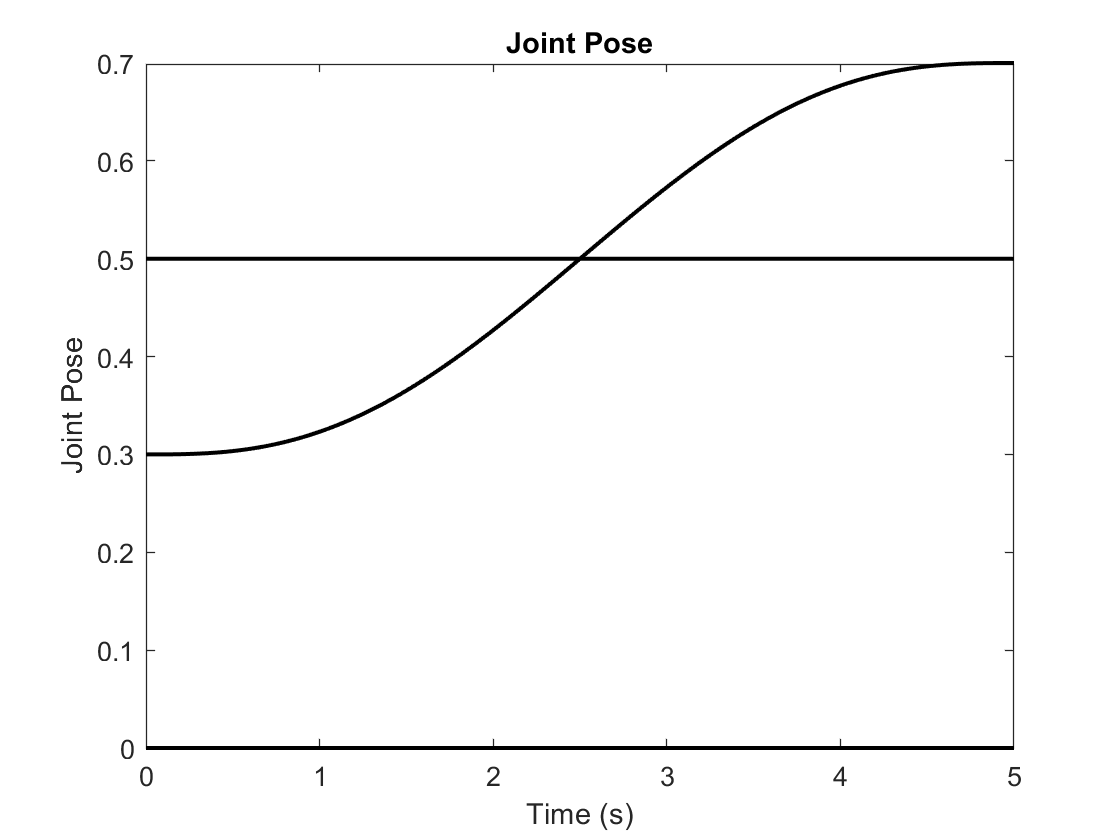

id_sim.plotJointPose();

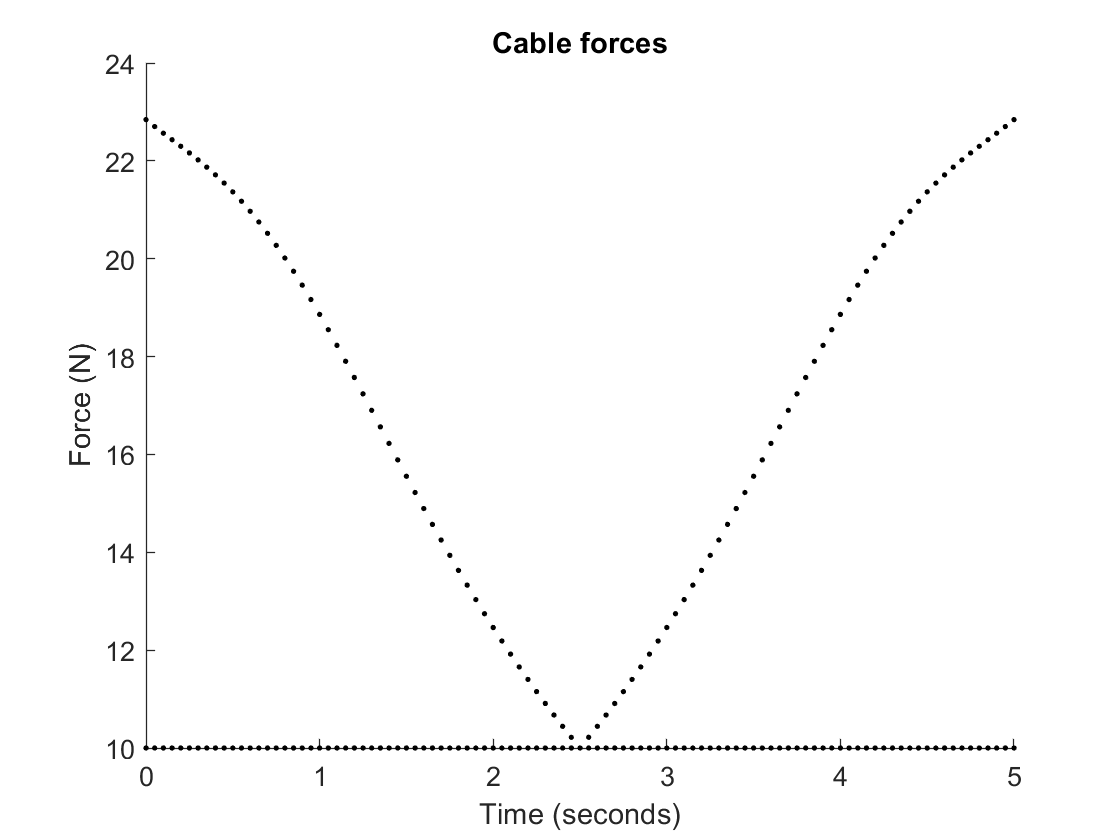

id_sim.plotCableForces();

## 2) Writing your own time loop

If you want more control over what is happening or customise the inner-workings during the simulation, it is recommended for you to write your own time loop to perform the inverse kinematics. The following simple example is basically what happens within the `InverseDynamicsSimulator`.

First, create the variables (pre-allocate memory) required to store the solution from the inverse kinematics (cable lengths and cable lengths velocity):

id_forces = zeros(cdpr_model.numCables, length(trajectory.timeVector)); % Each column is the solution at each time step

Next, loop through the trajectory as a function of time:

for t = 1:length(trajectory.timeVector)

The main step within the time loop is to compute the inverse dynamics using the solver's `resolve(q, q_dot, q_ddot, w_ext) `function, which requires the current pose, velocity and acceleration, and also external wrench, respectively. 

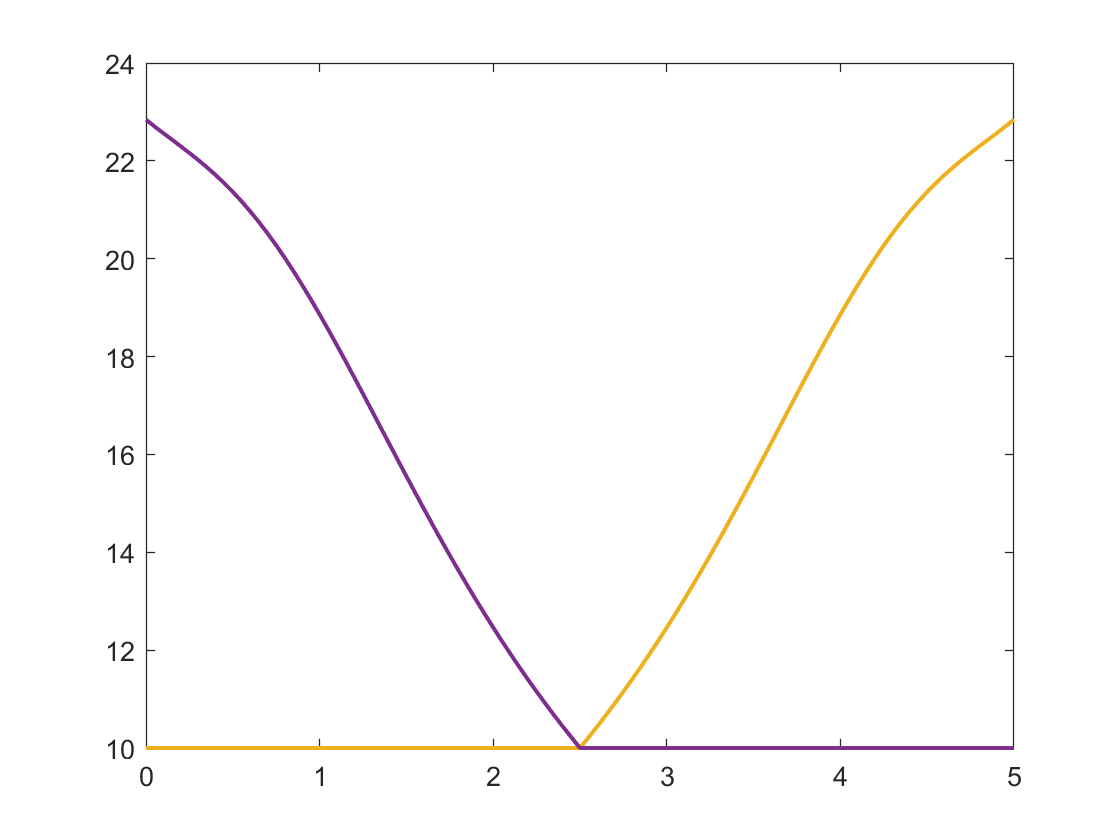

    [force_solution, cdpr_model, id_time_cost, id_exit_type, id_comp_time] = ...
        id_solver.resolve(trajectory.q{t}, trajectory.q_dot{t}, trajectory.q_ddot{t}, zeros(cdpr_model.numDofs,1));

    id_forces(:,t) = force_solution;
end

The function outputs:

- The solution forces vector

- Updated robot model with solution of cable forces and other related properties

- Computational time

- Exit condition for the solver: no error (success), infeasible, maximum iteration reached (for iterative solvers), solver specific error or other error. Refer to `IDSolverExitType.m` for more details

The results can be plotted the way you desire yourself.

figure; 
plot(trajectory.timeVector, id_forces, 'LineWidth', 1.5);

[INFO] Time : 0.000000
[INFO] Time : 0.050000
[INFO] Time : 0.100000
[INFO] Time : 0.150000
[INFO] Time : 0.200000
[INFO] Time : 0.250000
[INFO] Time : 0.300000
[INFO] Time : 0.350000
[INFO] Time : 0.400000
[INFO] Time : 0.450000
[INFO] Time : 0.500000
[INFO] Time : 0.550000
[INFO] Time : 0.600000
[INFO] Time : 0.650000
[INFO] Time : 0.700000
[INFO] Time : 0.750000
[INFO] Time : 0.800000
[INFO] Time : 0.850000
[INFO] Time : 0.900000
[INFO] Time : 0.950000
[INFO] Time : 1.000000
[INFO] Time : 1.050000
[INFO] Time : 1.100000
[INFO] Time : 1.150000
[INFO] Time : 1.200000
[INFO] Time : 1.250000
[INFO] Time : 1.300000
[INFO] Time : 1.350000
[INFO] Time : 1.400000
[INFO] Time : 1.450000
[INFO] Time : 1.500000
[INFO] Time : 1.550000
[INFO] Time : 1.600000
[INFO] Time : 1.650000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 1.700000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 1.750000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 1.800000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 1.850000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 1.900000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 1.950000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.000000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.050000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.100000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.150000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.200000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.250000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.300000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.350000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.400000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.450000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.500000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.550000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.600000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.650000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.700000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.750000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.800000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.850000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.900000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 2.950000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 3.000000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 3.050000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 3.100000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 3.150000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 3.200000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 3.250000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 3.300000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 3.350000
[INFO] Problem infeasible
[WARNING] No feasible solution for the ID


[INFO] Time : 3.400000
[INFO] Time : 3.450000
[INFO] Time : 3.500000
[INFO] Time : 3.550000
[INFO] Time : 3.600000
[INFO] Time : 3.650000
[INFO] Time : 3.700000
[INFO] Time : 3.750000
[INFO] Time : 3.800000
[INFO] Time : 3.850000
[INFO] Time : 3.900000
[INFO] Time : 3.950000
[INFO] Time : 4.000000
[INFO] Time : 4.050000
[INFO] Time : 4.100000
[INFO] Time : 4.150000
[INFO] Time : 4.200000
[INFO] Time : 4.250000
[INFO] Time : 4.300000
[INFO] Time : 4.350000
[INFO] Time : 4.400000
[INFO] Time : 4.450000
[INFO] Time : 4.500000
[INFO] Time : 4.550000
[INFO] Time : 4.600000
[INFO] Time : 4.650000
[INFO] Time : 4.700000
[INFO] Time : 4.750000
[INFO] Time : 4.800000
[INFO] Time : 4.850000
[INFO] Time : 4.900000
[INFO] Time : 4.950000
[INFO] Time : 5.000000
[WARNING] At least one point on the trajectory resulted in no feasible solution for the ID


## Simulation on an infeasible trajectory

When a trajectory is infeasible, the `resolve` function will return -1 for the cable force (shown in red in the cable forces plot) and exit type of `IDSolverExitType.INFEASIBLE`.

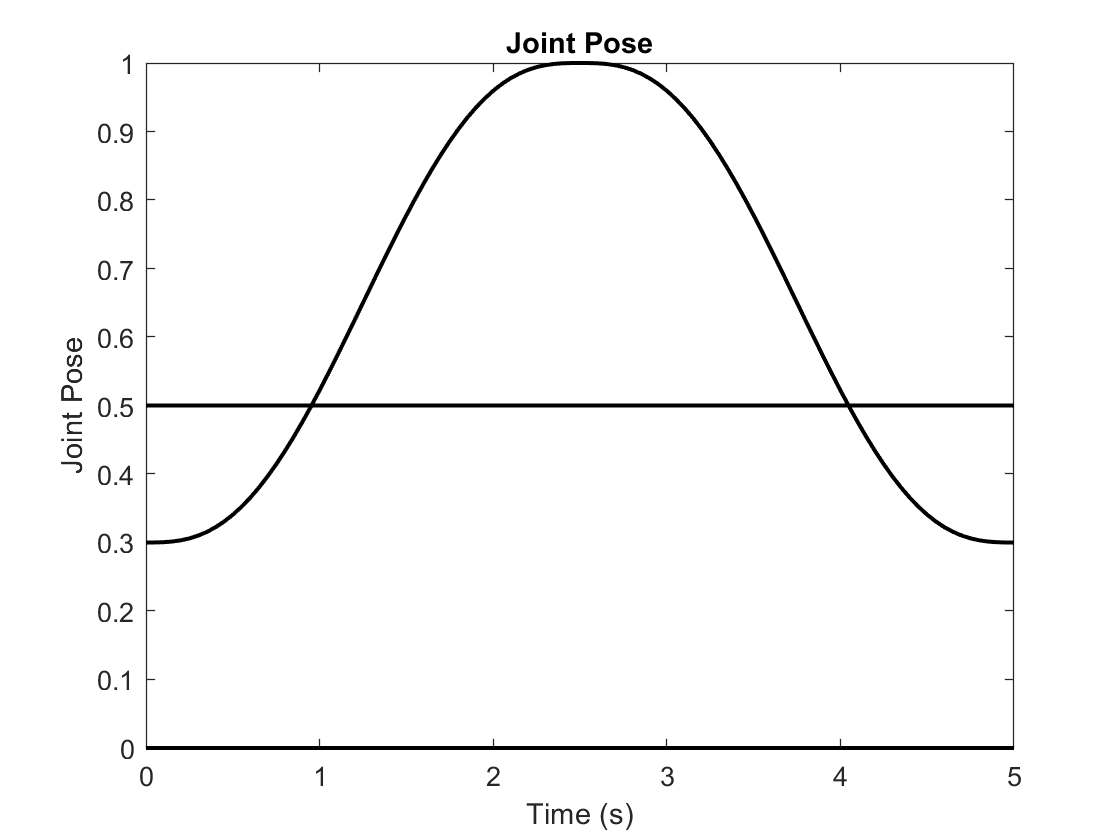

trajectory_infeasible = model_config.getJointTrajectory('example_infeasible');

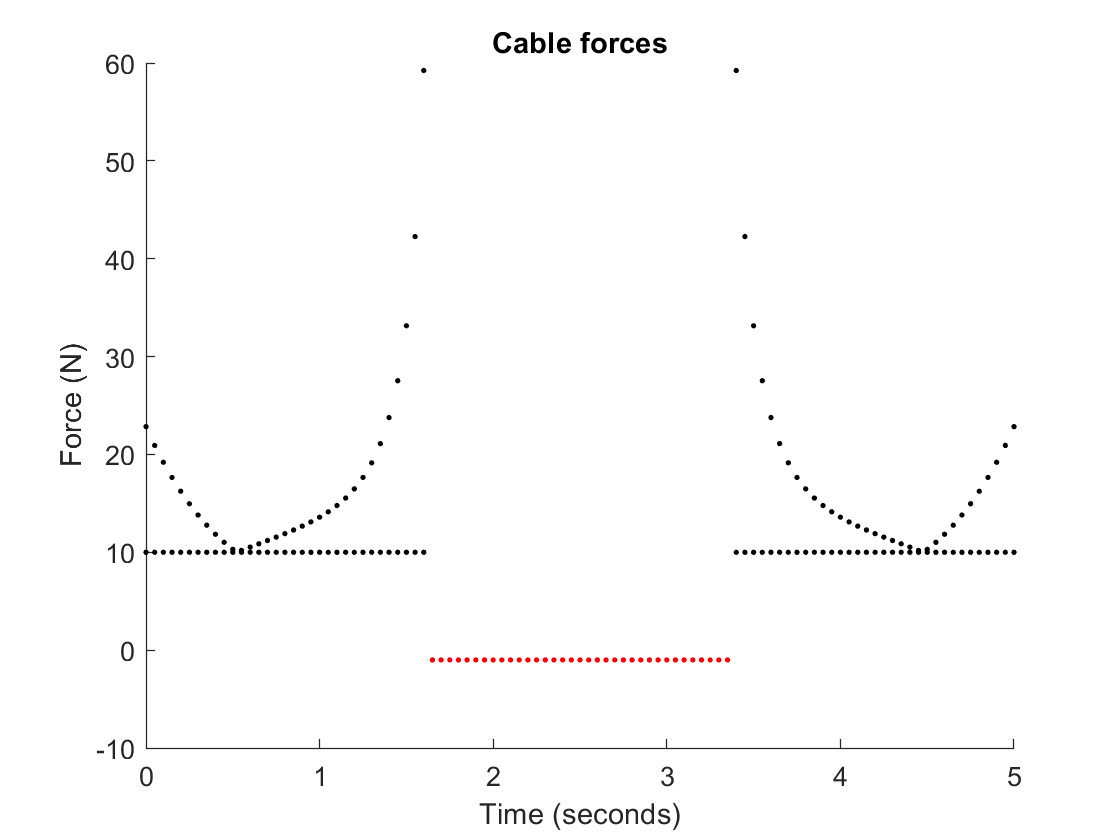

id_sim.run(trajectory_infeasible);

id_sim.plotJointPose();
id_sim.plotCableForces();

## Running another inverse dynamics solver

Another inverse dynamics solver, `IDSolverClosedForm`, will be shown to compare with the QP solver. Refer to `~/src/Analysis/InverseDynamics/` folder for more solvers that you can use.

% Setup the solver and simulator
id_solver_cf = IDSolverClosedForm(cdpr_model, ID_CF_SolverType.IMPROVED_CLOSED_FORM); % Refer to ~/src/Analysis/InverseDynamics/Solvers/IDSolverClosedForm.m for more information
id_sim_cf = InverseDynamicsSimulator(cdpr_model, id_solver_cf);
% Run the simulator
id_sim_cf.run(trajectory);

[INFO] Time : 0.000000
[INFO] Time : 0.050000
[INFO] Time : 0.100000
[INFO] Time : 0.150000
[INFO] Time : 0.200000
[INFO] Time : 0.250000
[INFO] Time : 0.300000
[INFO] Time : 0.350000
[INFO] Time : 0.400000
[INFO] Time : 0.450000
[INFO] Time : 0.500000
[INFO] Time : 0.550000
[INFO] Time : 0.600000
[INFO] Time : 0.650000
[INFO] Time : 0.700000
[INFO] Time : 0.750000
[INFO] Time : 0.800000
[INFO] Time : 0.850000
[INFO] Time : 0.900000
[INFO] Time : 0.950000
[INFO] Time : 1.000000
[INFO] Time : 1.050000
[INFO] Time : 1.100000
[INFO] Time : 1.150000
[INFO] Time : 1.200000
[INFO] Time : 1.250000
[INFO] Time : 1.300000
[INFO] Time : 1.350000
[INFO] Time : 1.400000
[INFO] Time : 1.450000
[INFO] Time : 1.500000
[INFO] Time : 1.550000
[INFO] Time : 1.600000
[INFO] Time : 1.650000
[INFO] Time : 1.700000
[INFO] Time : 1.750000
[INFO] Time : 1.800000
[INFO] Time : 1.850000
[INFO] Time : 1.900000
[INFO] Time : 1.950000
[INFO] Time : 2.000000
[INFO] Time : 2.050000
[INFO] Time : 2.100000
[INFO] Time

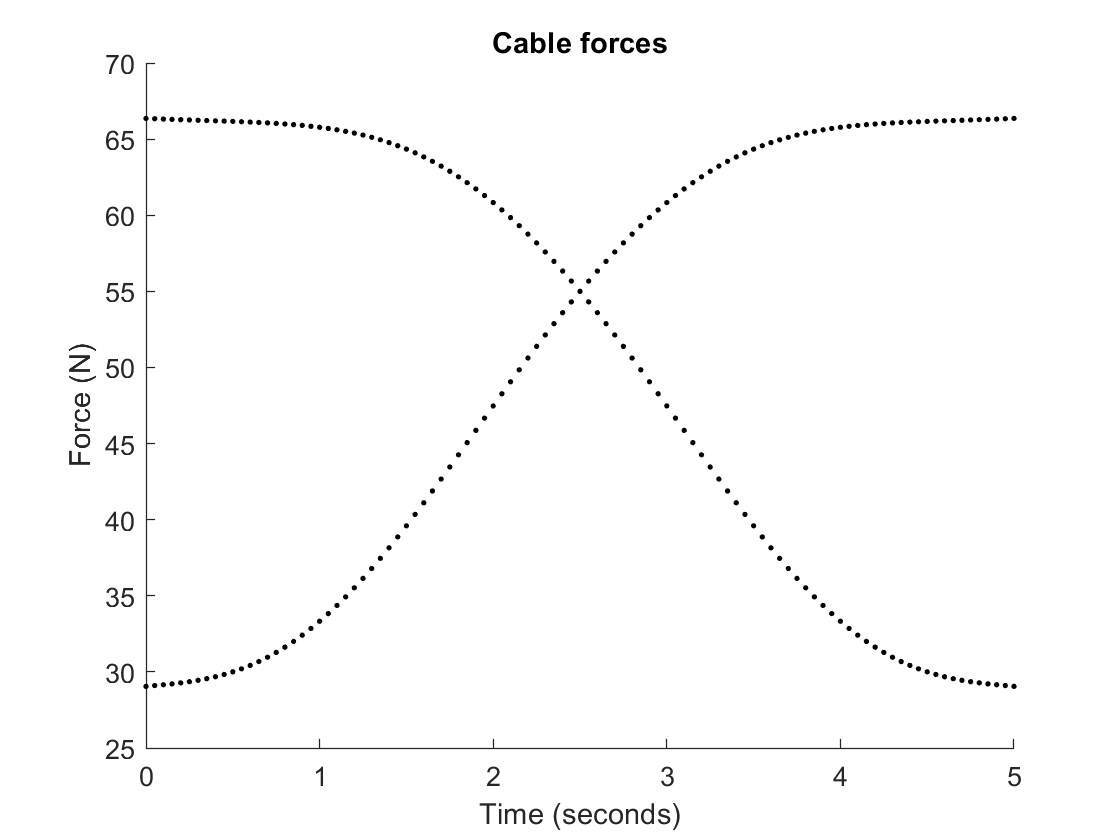

% Plot the results
id_sim_cf.plotCableForces();